# ELAB1

Pregunta 1

Pregunta 2

format long
Maxiter = 1000;

B = [4/5 -3/5 0;3/5 4/5 0;1 2 -2];
% Matriz
A = B + B';

% 1
Leig = -max(abs(eig(A)))

Leig =   -4.783294573433784



% 2
Tol = 1e-3;
Lqr1 = QRalg(A,Maxiter, Tol)

Lqr1 =   -4.783294573433783



% 3
Tol = 1e-4;
Lqr2 = QRalg(A,Maxiter, Tol)

Lqr2 =   -4.783294573433783



% 4
ERqr= abs(Leig - Lqr2)/abs(Leig)

ERqr =      1.856834042028335e-16



% 5
iqr=1


iqr =

     []



Pregunta 3

Pregunta 4

k1 = 150; k2 = 50; k3 = 75; k4 = 225;

A =    200   -50     0     0
   -50   125   -75     0
     0   -75   300  -225
     0     0  -225   225


dete = 126562500

rho = 0.9183

op = 1

decaprox =    10.1965   41.8108   64.2845   73.1734



% Item 1
A = [k2+k1 -k2 0 0; -k2 k3+k2 -k3 0; 0 -k3 k4+k3 -k4; 0 0 -k4 k4];
b = [0 0 0 2000]';

dete = det(A)

% Item 2
D = diag(diag(A));
L = -tril(A,-1);
U = -triu(A,1);

Tgs = inv(D-L)*U;

rho = radio_espectral(Tgs)

if (rho < 1)
    op = 1
else
    op = 0
end

% Item 3
x0 = [10 40 50 50]';

aprox = gausseidel_it(A, b, x0, 10);

decaprox = aprox(end, 1:4)

Pregunta 5

format long
% Paso 1
tiempo = 0:23; 
temperatura = [20, 22, 25, 28, 30, 32, 33, 34, 33, 31, 29, 27, 25, 23, 22, 21, 20, 19, 20, 22, 24, 26, 28, 29];

% Paso 2
G = tabladif(tiempo,temperatura);

% Paso 3
sum_dif_div = sum(sum(G(:, 3:end)))

sum_dif_div =    8.155131217101120



% Paso 4
coef = G(1, 3:end)

coef =    2.000000000000000   0.500000000000000  -0.166666666666667                   0   0.016666666666667  -0.008333333333333   0.002777777777778  -0.000768849206349   0.000187389770723  -0.000039958112875   0.000007340267757  -0.000001156572337   0.000000157057449  -0.000000018525254   0.000000001907967  -0.000000000170819   0.000000000012902  -0.000000000000733   0.000000000000013   0.000000000000004  -0.000000000000001   0.000000000000000  -0.000000000000000



Newton = polynewton(tiempo, temperatura)

Newton = 1.0e+05 *

  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000017   0.000000000000684  -0.000000000021177   0.000000000518404  -0.000000010192345   0.000000162573221  -0.000002116268899   0.000022540548599  -0.000196365725135   0.001394632202122  -0.008024277287337   0.037036785142737  -0.135193344704901   0.382467133805830  -0.814648617561061   1.251369520301769  -1.294264226819974   0.795729224906634  -0.215671041419156   0.000200000000000



% Paso 5
% 14 h con 23 min es igual a 14 h con 38.333 partes de hora  
temp_newton = polyval(Newton,14.383)

temp_newton =   21.686625161443267



%% Sí tiene sentido el resultado de temp_newton
if (temp_newton < 50 && temp_newton > -80)
    op = 1
else
    op = 0
end

op =      1


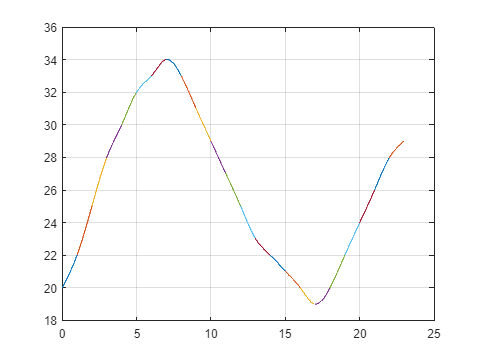


% Paso 6
spline = splinenatural(tiempo, temperatura);


% Paso 7
t = tiempo(12);
syms x
f = matlabFunction(spline(12, 1)*((x - t)^3) + spline(12,2)*((x - t)^2) + spline(12,3)*(x - t) + spline(12,4));

x0 = 11.01;
Tol = 1e-5;
hora26 = newton(f, x0, Tol);
hora26 = hora26(end)

hora26 =   16.623265628630552



% Paso 8


## Funciones

### Semana 2: Propagación de Errores y Punto Flotante

Cifras Significativas

function n = cifsig(A, a)
    n = floor(-log10(abs(A - a)/(5*abs(A))));
end

binary2Doble

function x = binary2Doble(b)
    % Extraiga los bits de signo, exponente y mantisa de la cadena.
    s = b(1);
    e = b(2:12);
    m = b(13:end);
    
    % Convierte los bits a valores decimales.
    signo= (-1)^(bin2dec(s));
    exp = bin2dec(e)-1024;
    frac= strcat('1',m);
    val = bin2dec(frac)*2^(-53);
    
    % Convierte a un número real usando el DEC Standard.
    x=signo*val*(2^exp);
end

Función arctan(x) con la aproximación de Taylor

function sol = arctan_taylor_it(x, n)
    sol = 0;

    for i = 0:n
        sol = sol + (-1)^i * (x^(2*i + 1))/(2*i + 1);
    end
end

Función para hallar la cantidad de términos necesarios para ciertas cifras significativas

function sol = arctan_taylor_nterm(x, n)
    nterm = 0;
    anterior = arctan_taylor_it(x, nterm);
    delta = 1;

    while (delta > 5 * 10^-n)   
        nterm = nterm + 1;
        actual = arctan_taylor_it(x, nterm);
        delta = abs(actual - anterior)/abs(actual);
        anterior = actual;
    end

    sol = nterm + 1;
end

Función para calcular de Decimal a Binario IEEE-754 precisión simple

function x = simple2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 24 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 127 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

Función para calcular de Decimal a binario IEEE-754 precisión doble

function x = double2binary(n)
    % Signo
    if n < 0 
        sign = "1";
    else
        sign = "0";
    end

    % Extraer la parte entera
    entero = floor(n);

    bin_ent = num2str(dec2bin(entero));

    % Extraer la parte decimal    
    b = mod(n, 10);
    bin_dec = "";
    
    for i = 1: 53 - length(bin_ent)
        if b < 1
            b = b * 2;
        else
            b = b - 1;
            b = b * 2;
        end
   
        bin_dec = bin_dec + num2str(floor(b));
    end

    % Mantiza
    mantiza = bin_ent(2:end) + bin_dec;

    % Exponente
    exp = 1023 + length(bin_ent(2:end));
    exp = num2str(dec2bin(exp));

    % Unión
    x = sign + exp + mantiza;
end

Función para convertir de binario IEEE - 754 presición simple a Decimal

function x = binary2dec_simple(b)
    s = b(1);
    e = b(2:9);
    m = b(10:32);

    dec_s = bin2dec(s);
    dec_e = bin2dec(e);
    dec_m = bin2dec(m)*2^(-length(m));
    x = (-1)^dec_s*2^(dec_e-127)*(1+dec_m);
end

Función para convertir de binario IEEE - 754 presición doble a Decimal

function x = binary2dec_double(b)
    s = b(1);
    e = b(2:12);
    m = b(13:64);

    dec_s = bin2dec(s);
    dec_e = bin2dec(e);
    dec_m = bin2dec(m)*2^(-length(m));
    x = (-1)^dec_s*2^(dec_e-1023)*(1+dec_m);
end

### Semana 3: Ecuaciones No Lineales de una variable

Método de Bisección con Tolerancia

function z = biseccion(f,a,b,Tol)
    c = (a+b)/2;
    error = (b-a)/2;
    z = [a b c f(a) f(b) f(c) error];
    N = ceil(log((b-a)/(2*Tol))/log(2));

    fprintf('Se necesita %d iteraciones\n', N)
    
    while error>Tol
        if f(a)*f(c)<0
            b = c;
        else
            a = c;
        end
        
        c = (a+b)/2;
        error = (b-a)/2;
        z = [z; a b c f(a) f(b) f(c) error];
    end

end

Método de Newton con tolerancia

function z = newton(f,x0,Tol)
    syms x
    df = diff(f(x));
    dfu = matlabFunction(df);
    z = x0;
    error = 1;

    while error > Tol
        x1 = x0 - f(x0)/dfu(x0);
        z = [z;x1];
        error = abs(x1-x0)/abs(x1);
        x0 = x1;
    end
end

Método de Punto Fijo con tolerancia

function z = puntofijo(g, x0, tol)
    error = 1;
    z = [x0 error];

    while error > tol
        x1 = g(x0);
        error = abs(x1 - x0)/abs(x1);
        z = [z; x1 error];
        x0 = x1;
    end
end

### Semana 4: Ecuaciones No Lineales de varias variables

Método de Newton Raphson

function z = newtonraphson(F, x0, Tol)
    syms x y
    dF = jacobian(F(x,y),[x,y]);
    df_fun = matlabFunction(dF);
    error=1;
    z = [x0' error];

    while error>Tol
        x1 = x0 - inv(df_fun(x0(1),x0(2))) * F(x0(1),x0(2));
        error = norm(x1 - x0, "inf")/norm(x1, "inf");
        z = [z; x1' error];
        x0 = x1;
    end
end

Método de Punto Fijo

### Semana 5: Sistemas de Ecuaciones Lineales

Función de Jacobi con tolerancia

function z = jacobi(A,b,x0,Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tj = inv(D)*(L+U);
    cj = inv(D)*b;

    error = 1;

    z = [x0' error];

    while error>Tol
        x1 = Tj*x0 + cj; 
        error = norm(x1-x0, "inf")/norm(x1, "inf");
        z = [z; x1' error];
        x0 = x1;
    end
end

Función de Gauss Seidel [tolerancia]

function z = gausseidel(A, b, x0, Tol)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tgs = inv(D-L)*U;
    cgs = inv(D-L)*b;
    error = 1;
    z = [x0' error];

    while error > Tol
        x1 = Tgs*x0 + cgs;
        error = norm(x1-x0,inf)/norm(x1,inf);
        z = [z;x1' error];
        x0 = x1;
    end
end

Función de Gauss Seidel [iterativa]

function z = gausseidel_it(A, b, x0, max)
    D = diag(diag(A));
    L = -tril(A,-1);
    U = -triu(A,1);

    Tgs = inv(D-L)*U;
    cgs = inv(D-L)*b;
    error = 1;
    z = [x0' error];

    for i = 1:max
        x1 = Tgs*x0 + cgs;
        error = norm(x1-x0,inf)/norm(x1,inf);
        z = [z;x1' error];
        x0 = x1;
    end
end

Criterio de convergencia por Diagonal estrictamente Dominante

function op = diagdom(A)
    % op = 0 si es Estrictamente Dominante
    % op = 1 si no lo es


    [m,n] = size(A);
    op = 0;
    
    if m == n
        for k = 1:m
            if abs(A(k,k)) <= sum(abs(A(k,:))) - abs(A(k,k))
                op = 1;
                break;
            end
        end
    end
end

Criterio de Convergencia por radio espectral

function re = radio_espectral(T)
    re = max(abs(eig(T)));
end

### Semana 7: Interpolación

Método de Lagrange

function p = lagrange(x,y)
    n = length(x);
    p = zeros(1,n);

    for k = 1:n
        num = poly(x([1:k-1,k+1:n]));
        den = polyval(num,x(k));
        L = num/den;
        p = p + y(k)*L;
    end
end

Tabla de diferencias divididas

function M = tabladif(x,y)
    n = length(x);
    M = zeros(n);
    M(1:n,1) = y;
    
    for k = 1:n-1
        delta_x = x(k+1:n)-x(1:n-k);
        delta_y = diff(y)./delta_x;
        M(1:n-k,k+1) = delta_y;
        y = delta_y;
    end
    
    M = [x' M];
end

Método de Newton

function p = polynewton(x, y)
    M = tabladif(x, y);
    n = length(x);
    b = M(1, 2:end);
    p = b(1);
    for k = 2:n
        p = [0 p] + b(k) * poly(x(1:k-1));
    end
end

### Semana 8: Spline cúbico

Función Spline Natural

function S=splinenatural(X,Y)
    N=length(X)-1;
    H=diff(X);
    E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N));
    diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E');
    g=A\b;
    g = [g0 g' gn];

    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    hold off
end

### Semana 9: Ajuste de Mínimos Cuadrados

Matriz Sobredeterminada

function [coef] = matrizSobre(x,y)
    % Matriz de coeficientes sobredeterminada
    % (Modificar por la función pedida)
    M = [x.^2 1./(x.^2+1) x];
    b = y;
    
    % Nueva matriz 2x2
    A = M' * M;
    b1 = M' * b;
    
    % Resolver la matriz
    coef = linsolve(A,b1);
    
    fprintf("a = %f\nb = %f\nc = %f", coef)
end

Función de mathlab para ajustar un polinomio de cierto grado n

function [] = ajustepoli(x,y,n)
    % Polyfit: Halla un polinomio que se ajusta a los puntos dados
    % Solo sirve para funciones polinomiales
    % OJITO: La función es de grado máximo (n-1), donde n es #puntos,
    % si se quisiera hallar de un grado mayor, solo devuelve una solución
    % de las múltiples existentes
    P = polyfit(x,y,n); 
    
    % Intervalo
    xx = -10:0.01:10;
    
    % Polyval: Evalúa el polinomio encontrado
    yy = polyval(P,xx);
    
    % 
    plot(x, y, 'or', xx, yy, 'b')
end

### Funciones Extra

Función de eliminación gaussiana

function [Ea,nb] = gauss(A,b)
    [m,n] = size(A);
    Aa = [A b];

    for k = 1:n-1
        pivo = Aa(k,k);

        for j = k+1:n
            mjk = Aa(j,k)/pivo;
            Aa(j,:) = Aa(j,:) - mjk*Aa(k,:);
        end
    end

    Ea = Aa(:,1:n);
    nb = Aa(:,n+1);
end

Función de sustitución regresiva

function [x] = sustireg(Ea,b)
    U = triu(Ea);
    % U: Matriz triangular superior
    [m,n] = size(U);
    x = zeros(n,1);

    for k = n:-1:1
        x(k)=(b(k)- U(k,k+1:n)*x(k+1:n))/U(k,k);
    end
end

function [Q, R]=gs_c(A)
[m,n]=size(A);
Q=zeros(m,n);
R=zeros(n);
    for j=1:n
    R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
    temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
    R(j,j)=norm(temp);
    Q(:,j)=temp/R(j,j);
    end
end

function L=QRalg(A,MaxIter,Tol)
% A: matriz cuadrada
% MaxIter: número de iteraciones (puede fijarlo a 1000)
% Tol: nivel de tolerancia
% L: valor prpopio dominante de A

T=A;
for i=1:MaxIter
    [Q, R] = gs_c(T);
    T = R * Q;
    L = T(1,1);
    
    if (norm(T - diag(T), "inf") < Tol)
        break;
    end
end
end